# test

mycell = {1, 2, [], 3};
a = cellfun(@isempty, mycell)

a = 1×4 logical 数组
   0   0   1   0


mycell(a) = []

mycell = 1×3 cell 数组
    {[1]}    {[2]}    {[3]}


addpath(genpath(".\lib\util"))


cu = clr_util()

cu = 包含以下字段的 struct :
         info: @info
      allclrs: @get_allclrs
    demo_plot: @demo_plot


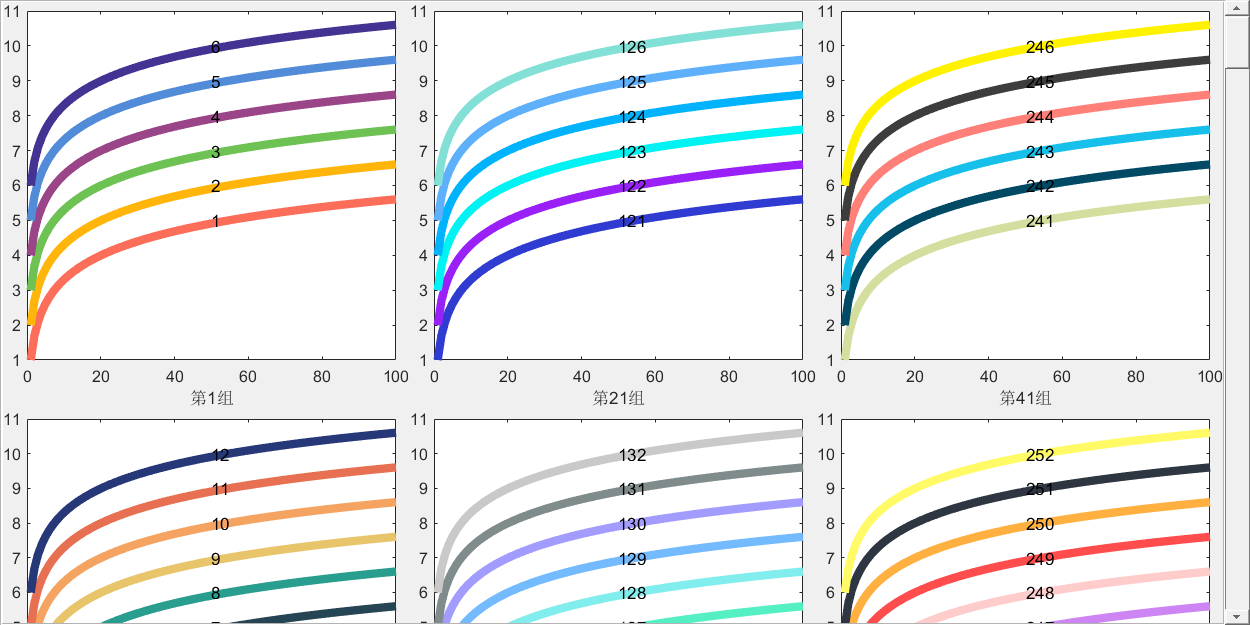

cu.demo_plot()

num = 4
parpool(num)
parfor i=1:10
    c(:,i) = eig(rand(1000)); 
end
delete(gcp('nocreate'));
a=mean(c)

    %create uifigure
    uif_obj = uifigure("Name", "reminder", "Position", [450,120,400,200]);

    remind_msg = ['The cache may contain unsaved data.', newline ,...
        ' Do you want to delete this possibly unsaved data?(default: no)', newline, ...
        'Remaining time(s):'];
    time = 6; 
    
    %create uilabel
    uilabel_obj = uilabel("Parent", uif_obj, ...
        "Text", [remind_msg, num2str(time)], ...
        "Position", [20,60,350,150]);
    
    %yes button
    uibutton(uif_obj, "Text", "yes", "Position", [100,50,48,20], "ButtonPushedFcn", @callback_ybt);

    %no button
    nbt_obj = uibutton(uif_obj, "Text", "no", "Position", [250,50,48,20], "ButtonPushedFcn", @callback_nbt);
    
    pause(1)

    for i = 1:time - 1
        time = time - 1;
        if ~isvalid(uilabel_obj)
            break
        end
        uilabel_obj.Text = [remind_msg, num2str(time)];
        pause(1)
    end

%     callback_nbt(nbt_obj);


%     %yes button callback

diary(".\.temp\.LogFiles\log")
num = 4
disp(num)
diary off



funvarargin(1, 'Darrius')

clear
clc

a = 0;
if a
    b = 1;
end

if exist("b", "var")
    disp(b)
else
    disp(2)
end

list = {'Red','Yellow','Blue',...                   
'Green','Orange','Purple'};
[indx,tf] = listdlg('ListString',list);
indx


indx =

     []



tf

tf = 0

function callback_ybt(obj, ~)
    delete(obj.Parent);
end

%no button callback
function callback_nbt(obj, ~)
    delete(obj.Parent);
end

function funvarargin(varargin)
    disp(varargin)
end